**Defining the parameters:**

xmin = 0

xmin = 0

xmax = 3

xmax = 3

Nx = 31

Nx = 31

courant_number = 0.5

courant_number = 0.5000

delta_x = 0.1

delta_x = 0.1000

gamma = 1.4

gamma = 1.4000

x = linspace(0,3,Nx)

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000


area = @(x)(1 + 2.2*(x-1.5).^2);
A = area(x)

A =     5.9500    5.3120    4.7180    4.1680    3.6620    3.2000    2.7820    2.4080    2.0780    1.7920    1.5500    1.3520    1.1980    1.0880    1.0220    1.0000    1.0220    1.0880    1.1980    1.3520    1.5500    1.7920    2.0780    2.4080    2.7820    3.2000    3.6620    4.1680    4.7180    5.3120    5.9500


throat_index = 1.5/(delta_x) + 1

throat_index = 16

**The following functions are used in the Numerical Solution**

Initialization Function :

[density,temperature,velocity] = initialize_flow_variables(Nx,Nt,delta_x);

Boundary Conditions are Applied:

[density,temperature,velocity] = boundary_condition(density,temperature,velocity);

The time-step is calculated:

[delta_t] = timestep(temperature_at_t,velocity_at_t,delta_x,C)

The McCormack method is applied and the solution is marched in time:

tic
[density,velocity,temperature,pressure,mach,mass_flow_rate_memory,pressure_throat,density_throat,velocity_throat,temperature_throat,Mach_throat,iter] = McCormack(Nx,x,delta_x,A,gamma,throat_index,courant_number);
toc

Elapsed time is 0.217913 seconds.


%We measure the time taken 
time_numerical = toc ;

%We plot the mass flow rate

figure(1);
hold on;
iter_list = [50,200,300,1800]

iter_list =           50         200         300        1800


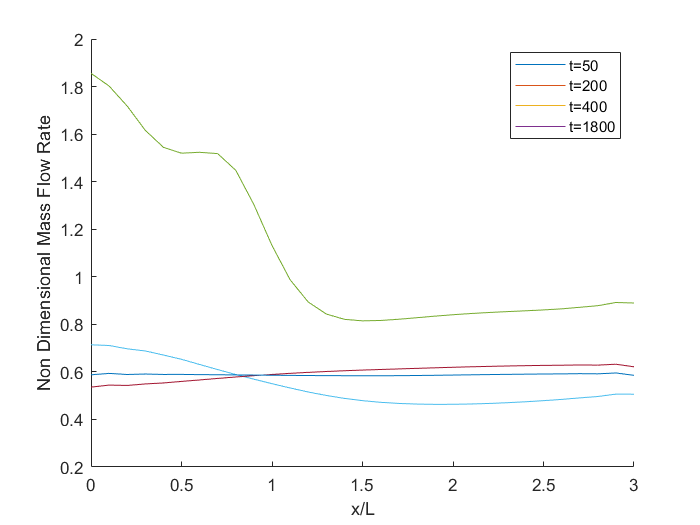

for i = 1:4
    plot(x,mass_flow_rate_memory(iter_list(i),:))
end
xlabel('x/L');
ylabel('Non Dimensional Mass Flow Rate')
legend('t=50','t=200','t=400','t=1800')
axis([0 x(end) 0.2 2])

hold off;

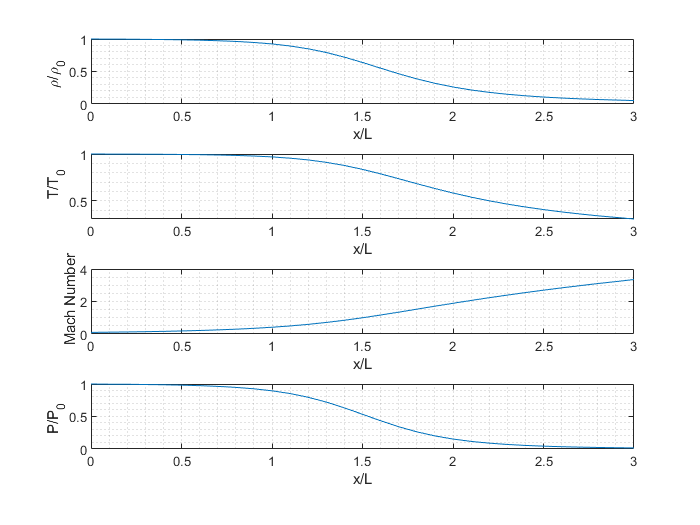

% We plot the final profiles
figure(2);
subplot(4,1,1)
plot(x,density)
xlabel('x/L')
ylabel('\rho/\rho_0 ')

grid minor;


subplot(4,1,2)
plot(x,temperature)
xlabel('x/L')
ylabel(' T/T_0')
grid minor;

subplot(4,1,3)
plot(x,mach)
xlabel('x/L')
ylabel(' Mach Number')
grid minor;

subplot(4,1,4)
plot(x,pressure)
xlabel('x/L')
ylabel('P/P_0 ')
grid minor;

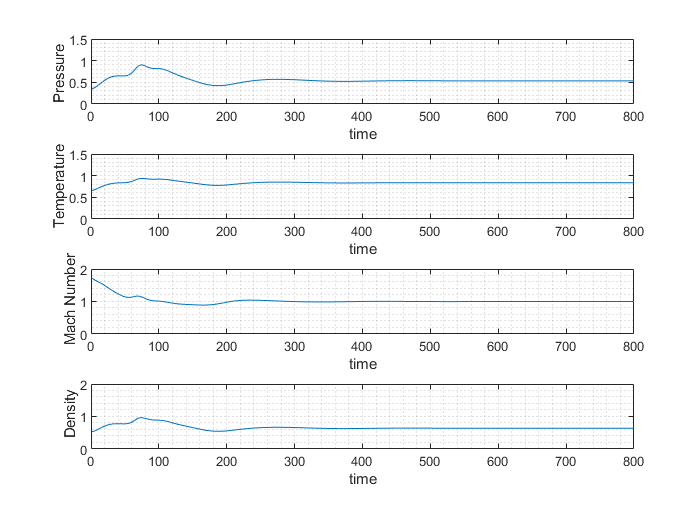

%We plot the time convergence at the throat.
figure(3);


subplot(4,1,1)
plot(pressure_throat)
xlabel('time')
ylabel('Pressure ')
axis([0,800,0,1.5])
grid minor;


subplot(4,1,2)
plot(temperature_throat)
ylabel('Temperature')
xlabel('time')
axis([0,800,0,1.5])
grid minor;

subplot(4,1,3)
plot(Mach_throat)
xlabel('time')
ylabel(' Mach Number')
axis([0,800,0,2])
grid minor;


subplot(4,1,4)
plot(density_throat)
xlabel('time')
ylabel(' Density')
axis([0,800,0,2])
grid minor;

**Generating Data from Analytical solution:**

tic
%Credits:https://in.mathworks.com/matlabcentral/answers/482917-area-mach-number-relation
% Solve for Msub and Msup using this area ratio (A/A*)
ARatio = A;
% Define some paramters
g   = 1.4;
gm1 = g-1;
gp1 = g+1;
% Define anonymous function with two inputs (M and ARatio)
% - Will be used in the methods below
% - Pass M and ARatio as arguments to AM_EQN to get function value
% -     funVal = AM_EQN(M,ARatio)
AM_EQN = @(M,ARatio) sqrt((1/M^2)*(((2+gm1*M^2)/gp1)^...
    (gp1/gm1)))-ARatio;
for k = 1:numel(ARatio)
    % Error tolerance
    errTol = 1e-4;
    % Flags for printing iterations to screen
    verboseBisection   = 0;
    verboseIncremental = 0;
    %% SUBSONIC INCREMENTAL SEARCH
    % Initial values
    dM       = 0.1;                                                             % Initial M step size
    M        = 1e-6;                                                            % Initial M value
    iConvSub = 0;                                                               % Initial converge index
    if (verboseIncremental == 1)
        fprintf('Incremental Search Method: Subsonic\n');
        fprintf('-----------------------------------\n');
    end
    % Iterate to solve for root
    iterMax = 100;                                                              % Maximum iterations
    stepMax = 100;                                                              % Maximum step iterations
    for i = 1:1:iterMax
        for j = 1:1:stepMax
            
            % Evaluate function at j and j+1
            fj   = AM_EQN(M,ARatio(k));
            fjp1 = AM_EQN(M+dM,ARatio(k));
            
            % Print iterations to command window
            if (verboseIncremental == 1)
                fprintf('fj | fjp1: %3.4f\t%3.4f\n',fj,fjp1);
            end
            
            % Update M depending on sign change or not
            % - If no sign change, then we are not bounding root yet
            % - If sign change, then we are bounding the root, update dM
            if (fj*fjp1 > 0)
                M = M + dM;                                                     % Update M
            elseif (fj*fjp1 < 0)
                dM = dM*0.1;                                                    % Refine the M increment
                break;                                                          % Break out of j loop
            end
            
        end % END: j Loop
        
        % Check for convergence
        if (abs(fj-fjp1) <= errTol)                                             % If converged
            iConvSub = i;                                                       % Set converged index
            break;                                                              % Exit loop
        end
        
    end % END: i Loop
    % Set subsonic Mach number to final M from iterations
    Msub = M;
    %% SUPERSONIC INCREMENTAL SEARCH
    % Initial values
    dM       = 1;                                                               % Initial M step size
    M        = 1+1e-6;                                                          % Initial M value
    iConvSup = 0;                                                               % Initial converge index
    if (verboseIncremental == 1)
        fprintf('\nIncremental Search Method: Supersonic\n');
        fprintf('-------------------------------------\n');
    end
    % Iterate to solve for root
    iterMax = 100;                                                              % Maximum iterations
    stepMax = 100;                                                              % Maximum step iterations
    for i = 1:1:iterMax
        for j = 1:1:stepMax
            
            % Evaluate function at j and j+1
            fj   = AM_EQN(M,ARatio(k));
            fjp1 = AM_EQN(M+dM,ARatio(k));
            
            % Print iterations to command window
            if (verboseIncremental == 1)
                fprintf('fj | fjp1: %3.4f\t%3.4f\n',fj,fjp1);
            end
            
            % Update M depending on sign change or not
            % - If no sign change, then we are not bounding root yet
            % - If sign change, then we are bounding the root, update dM
            if (fj*fjp1 > 0)
                M = M + dM;                                                     % Update M
            elseif (fj*fjp1 < 0)
                dM = dM*0.1;                                                    % Refine the M increment
                break;                                                          % Break out of j loop
            end
            
        end % END: j Loop
        
        % Check for convergence
        if (abs(fj-fjp1) <= errTol)                                             % If converged
            iConvSup = i;                                                       % Set converged index
            break;                                                              % Exit loop
        end
        
    end % END: i Loop
    % Set supersonic Mach number to final M from iterations
    Msup = M;
    
    i = k; 
    if(i<=16)
    Mach_Analytical(i) = Msub;
    else
    Mach_Analytical(i) = Msup;
    end
    %Throat
    Mach_Analytical(16) = 1;

end
Temperature_Analytical = (1 + (g-1)/2*Mach_Analytical.^2).^(-1)

Temperature_Analytical =     0.9981    0.9976    0.9969    0.9961    0.9949    0.9932    0.9909    0.9877    0.9831    0.9765    0.9670    0.9535    0.9345    0.9087    0.8749    0.8333    0.7854    0.7335    0.6807    0.6296    0.5818    0.5382    0.4991    0.4642    0.4333    0.4058    0.3814    0.3597    0.3403    0.3228    0.3071


Density_Analytical = (1 + (g-1)/2*Mach_Analytical.^2).^(-1/(g-1))

Density_Analytical =     0.9952    0.9940    0.9924    0.9902    0.9872    0.9832    0.9775    0.9696    0.9583    0.9423    0.9196    0.8878    0.8443    0.7871    0.7160    0.6339    0.5466    0.4608    0.3824    0.3145    0.2582    0.2125    0.1760    0.1468    0.1236    0.1049    0.0899    0.0776    0.0675    0.0592    0.0523


toc

Elapsed time is 0.108587 seconds.



time_analytical = toc 

time_analytical = 0.1127

**We now compare the analytical and numerical solutions:**

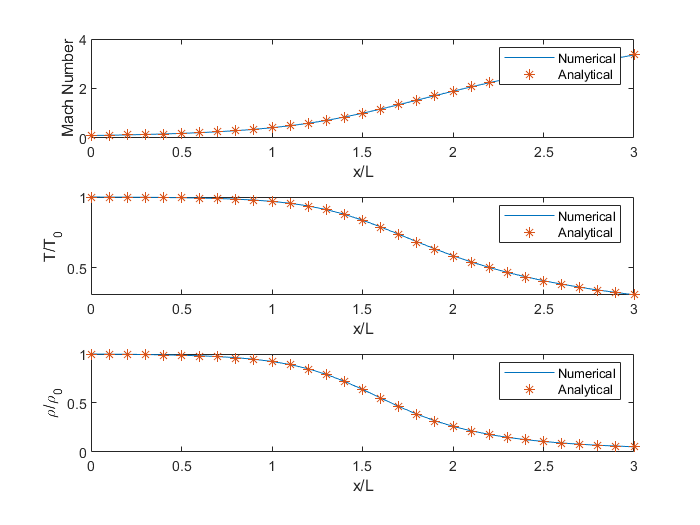

figure(4);
title('Analytical Solution vs Numerical Solution')
subplot(3,1,1)

plot(x,mach)
hold on ;
plot(x,Mach_Analytical,'*')

legend('Numerical','Analytical ') 
xlabel('x/L')
ylabel('Mach Number')
hold off;


subplot(3,1,2)

plot(x,temperature)
hold on ;
plot(x,Temperature_Analytical,'*')

legend('Numerical','Analytical ') 
xlabel('x/L')
ylabel('T/T_0')
hold off;


subplot(3,1,3)

plot(x,density)
hold on ;
plot(x,Density_Analytical,'*')

legend('Numerical','Analytical ') 
xlabel('x/L')
ylabel('\rho/\rho_0')
hold off;

%Mean Square Error Calculation:
Mach_error = 1/31 * sum((Mach_Analytical - mach).^2)

Mach_error = 3.0799e-05

Density_error = 1/31* sum((Density_Analytical - density).^2)

Density_error = 1.4859e-05

Temperature_error = 1/31* sum((Temperature_Analytical - temperature).^2)

Temperature_error = 5.9295e-06

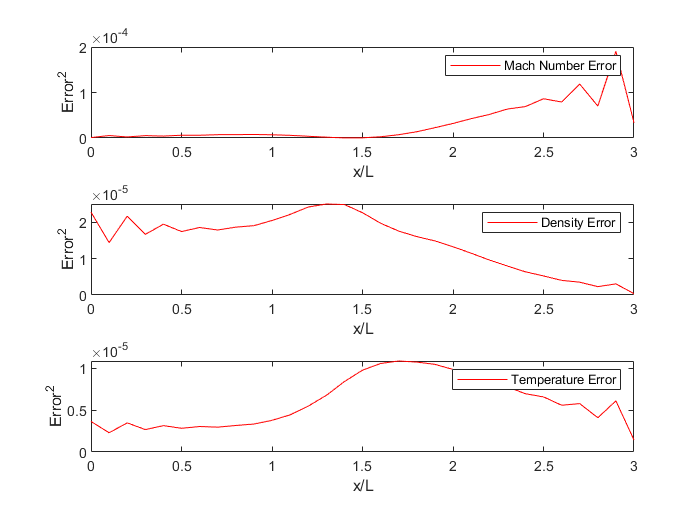

%We plot the squared error values along the nozzle at steady state
figure(5);
subplot(3,1,1)
plot(x,(Mach_Analytical - mach).^2,'r')
xlabel('x/L')
ylabel('Error^2')
legend('Mach Number Error')
subplot(3,1,2)
plot(x,(Density_Analytical - density).^2,'r')
xlabel('x/L')
ylabel('Error^2')
legend('Density Error')

subplot(3,1,3)
plot(x,(Temperature_Analytical - temperature).^2,'r')
xlabel('x/L')
ylabel('Error^2')
legend('Temperature Error')

% We compare the obtained values at the Nozzle
fprintf('Mach Numerical')

Mach Numerical

mach(16)

ans = 0.9994

fprintf('Mach Analytical')

Mach Analytical

Mach_Analytical(16)

ans = 1

fprintf('Density Numerical')

Density Numerical

density(16)

ans = 0.6387

fprintf('Density Analytical')

Density Analytical

Density_Analytical(16)

ans = 0.6339

fprintf('Temperature Numerical')

Temperature Numerical

temperature(16)

ans = 0.8365

fprintf('Temperature Analytical')

Temperature Analytical

Temperature_Analytical(16)

ans = 0.8333

fprintf('Analytical Solution Time')

Analytical Solution Time

time_analytical

time_analytical = 0.1127

fprintf('Numerical Solution Time')

Numerical Solution Time

time_numerical

time_numerical = 0.2289